N = 1000; %sample length
signal_power = 1; %signal power (Ps)
snr_db = [-5, 0, 5, 10, 15]; %SNR values in dB to simulate
error_rates = zeros(length(snr_db)); %Preallocate error rates array

%%% AT THE NODES %%%

%Transmit Bits
node_transmitted_signal_A = 2*randi([0 1], 1, N) - 1;    %generate signal A
node_transmitted_signal_B = 2*randi([0 1], 1, N) - 1;    %generate signal B

for i = 1:length(snr_db)
    %%% IN THE CHANNEL %%%

    %Configure Noise
    snr = 10^(snr_db(i)/10); %convert SNR from dB to linear scale
    noise_power = signal_power / snr; %calculate noise power

    %Generate Noise
    noise_A = sqrt(noise_power) * randn(1, N); %generate AWGN noise
    noise_B = sqrt(noise_power) * randn(1, N); %generate AWGN noise

    %Add Noise
    relay_received_signal_A = node_transmitted_signal_A + noise_A; %received signal
    relay_received_signal_B = node_transmitted_signal_B + noise_B; %received signal

    %%% AT THE RELAY %%%
    
    %Apply Detection Rule
    relay_detected_signal_A = relay_received_signal_A > 0;
    relay_detected_signal_B = relay_received_signal_B > 0;

    %Combine Signals
    combined_signal = xor(relay_detected_signal_A, relay_detected_signal_B);
    relay_transmitted_signal = double(combined_signal);

    %Convert Zeros to Negative Ones
    relay_transmitted_signal(relay_transmitted_signal == 0) = -1;

    %%% IN THE CHANNEL %%%

    %Generate Noise
    noise = sqrt(noise_power) * randn(1, N); %generate AWGN noise

    %Add Noise
    node_received_signal = relay_transmitted_signal + noise;

    %%% AT THE NODES %%%

    %Apply Detection Rule
    node_detected_signal = node_received_signal > 0;
    original_signal_A = node_transmitted_signal_A > 0;
    original_signal_B = node_transmitted_signal_B >0;

    %Deconstruct Signal
    deconstructed_signal_A = xor(node_detected_signal, original_signal_B);
    deconstructed_signal_B = xor(node_detected_signal, original_signal_A);
    deconstructed_signal_A = double(deconstructed_signal_A);
    deconstructed_signal_B = double(deconstructed_signal_B);

    %Convert Zeros to Negative Ones
    deconstructed_signal_A(deconstructed_signal_A == 0) = -1;
    deconstructed_signal_B(deconstructed_signal_B == 0) = -1;

    %Calculate and Store Error Rate
    error_rate_A = sum(node_transmitted_signal_A ~= deconstructed_signal_A)/N;
    error_rate_B = sum(node_transmitted_signal_B ~= deconstructed_signal_B)/N;
    error_rate_avg = mean([error_rate_A, error_rate_B])
    error_rates(i) = error_rate_avg;
end

error_rate_avg = 0.4710

error_rate_avg = 0.3520

error_rate_avg = 0.1040

error_rate_avg = 0.0020

error_rate_avg = 0

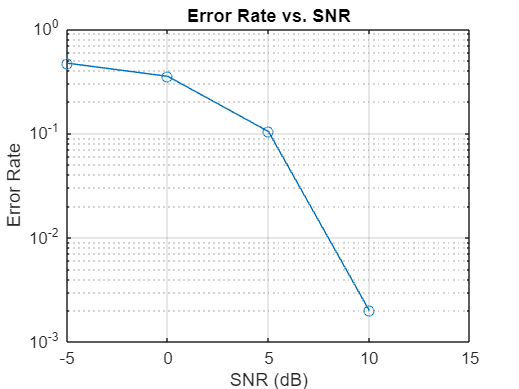


%Plot Error Rate vs SNR
figure;
semilogy(snr_db, error_rates, 'o-');
title('Error Rate vs. SNR');
xlabel('SNR (dB)');
ylabel('Error Rate');
grid on;